clc
clear

% syms theta1 theta2 d3 theta4
% syms L1 L2
%%% Valores_Articulares %%%
theta1 = input('Ingrese valor de theta1: ')

theta1 = 11

theta2 = input('Ingrese valor de theta2: ')

theta2 = 28

d3 = input('Ingrese valor de d3(Negativo): ')

d3 = -14.4330

theta4 = input('Ingrese el valor de theta4: ')

theta4 = 29.7440


%%% Datos %%%
L1 = 225;
L2 = 175;

%%% Tabla_DH %%%

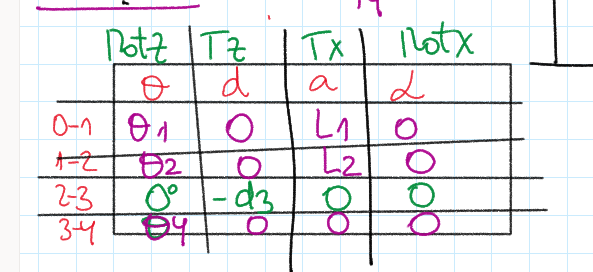


%%% Conversión_Grados ---> Radianes %%%
% tic
theta1 = deg2rad(theta1);
theta2 = deg2rad(theta2);
theta4 = deg2rad(theta4);

%%% Implementación_de_DH %%%
M01 = DHL(theta1,0,L1,0);
M12 = DHL(theta2,0,L2,0);
M23 = DHL(0,d3,0,0);
M34 = DHL(theta4,0,0,0);

M04 = M01*M12*M23*M34

M04 =     0.3625   -0.9320         0  356.8667
    0.9320    0.3625         0  153.0631
         0         0    1.0000  -14.4330
         0         0         0    1.0000


function M=DHL(theta,d,a,alpha)

Mrot_z = [cos(theta) -sin(theta) 0 0
          sin(theta)  cos(theta) 0 0
          0           0          1 0
          0           0          0 1];

transl = [1 0 0 a
          0 1 0 0
          0 0 1 d
          0 0 0 1];
Mrot_x = [rotx(alpha) [0;0;0]
          0 0 0        1];

M=Mrot_z*transl*Mrot_x;
end

